clc
clear all

goal_x=3.82

goal_x = 3.8200

goal_y =2.99

goal_y = 2.9900

theta_g = 0.77

theta_g = 0.7700

pos_x = zeros(1,1000);
pos_x(1) = 5.54;
pos_y=zeros(1,1000);
pos_y(1) = 5.54;
theta_ = zeros(1,1000);

er_x = goal_x-pos_x(1);
er_y = goal_y-pos_y(1);
theta_er_ = theta_g - theta_(1);


while abs(er_x) < 0.1 && abs(theta_er_) < 0.3 && abs(er_y) < 0.1
    goal_x = randi([1,10])
    goal_y = randi([1,10])
    theta_g = -1.57 + (1.57 + 1.57) * rand()
    er_x = goal_x-pos_x(1);
    er_y = goal_y-pos_y(1);
    theta_er_ = theta_g - theta_(1);
end


%time 
dt=0.016;

%velocity error
V_x = er_x/dt;
V_y = er_y/dt;
omega_ = theta_er_/dt;

for i = 1:999
    w_(i) = 0.006 * (omega_) + 0.00045 * omega_ * dt + 0.00003 * (omega_ / dt);
    u(i) = cos(theta_(i)) * ((0.1 * (V_x) + 0.0006 * V_x * dt + 0.00002 * (V_x / dt))) + sin(theta_(i)) * ((0.1 * (V_y) + 0.0006 * V_y * dt + 0.00002 * (V_y / dt)));
    v(i) =-sin(theta_(i)) * ((0.1 * (V_x) + 0.0006 * V_x * dt + 0.00002 * (V_x / dt))) + cos(theta_(i)) * ((0.1 * (V_y) + 0.0006 * V_y * dt + 0.00002 * (V_y / dt)));

    theta_(i+1) = theta_(i) + w_(i)*dt;

    %change the body velocity to velocity in world frame reference
    pos_x(i+1) = pos_x(i) + (cos(theta_(i)) * u(i) - sin(theta_(i)) * v(i))*dt;
    pos_y(i+1) = pos_y(i) + (sin(theta_(i)) * u(i) + cos(theta_(i)) * v(i))*dt;
    
    %recompute errors
    er_x = pos_x(i+1) - pos_x(i);
    er_y = pos_y(i+1) - pos_y(i);
    theta_er_ = theta_g - theta_(i+1);
    
    %recompute velocities
    V_x = er_x/dt;
    V_y = er_y/dt;
    omega_ = theta_er_/dt;
end

i = 1:1000

i =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


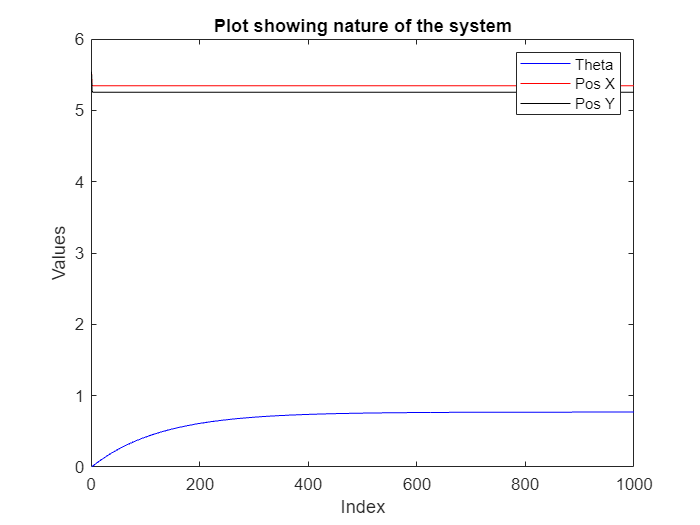


% Create a new figure
figure;

% Plot the first line (blue)
plot(i, theta_, "Color", "blue");
hold on;  % Enable hold mode to add more plots to the same figure

% Plot the second line (red)
plot(i, pos_x, "Color", "red");

% Plot the third line (black)
plot(i, pos_y, "Color", "black");

% Set labels and title
xlabel('Index');
ylabel('Values');
title('Plot showing nature of the system');

% Add a legend
legend('Theta', 'Pos X', 'Pos Y');

% Turn off hold mode to prevent further plots from being added
hold off;